# Projet M2 AURO EKF-SLAM

clc
clear all
close all

## Creation de la carte

La carte est composée de 8 amers dont le robot ne connait pas l'emplacement a priori. Nous allons créer une matrice 2x8 contenant la l'abscisse et l'ordonnnées de la position de chaque amer.


% Matrice contenant les position (X,Y) de chaque amer
Lm=[3, 5, 7, 9, 3, 5, 7, 9 ; 4, 4, 4, 4, 2, 2, 2, 2]

Lm =      3     5     7     9     3     5     7     9
     4     4     4     4     2     2     2     2


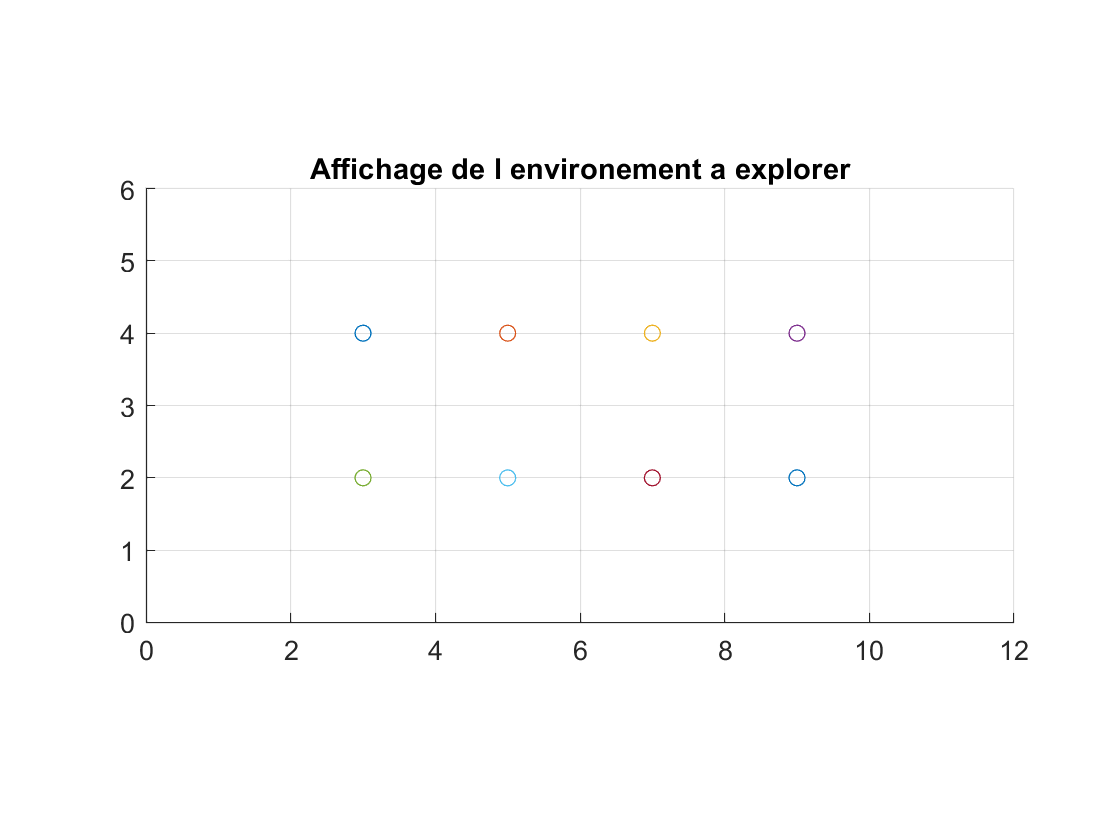


% Affichage de la carte
for k = 1 : length(Lm)
    scatter(Lm(1,k),Lm(2,k))
    title("Affichage de l environement a explorer")
    axis equal
    xlim([0 12])
    ylim([0 6])   
    hold on
    grid on
end

## Creation d une commande pour le robot

Le vecteur Uk contient la commande pour chaque instant k la [(TauXk,TauYk)',Rhok]'

% for i=1:9
%     Uk(:,i)=[i;0;0] 
% end 
% 
% Uk(:,10)=[0;2;pi/4]
% 
% 
% 
% for i=11:18
%     Uk(:,i)=[i;0;0] 
% end

w=-pi/4;
deltaT=0.01;
X=1; % Deplacement d une unite
% Matrice de passage homegene pour une rotation autour de l axe Z
 
Fr =[cos(w*deltaT) ,-sin(w*deltaT) , 0 1; sin(w*deltaT) cos(w*deltaT), 0 -1; 0 , 0, 1, 0; 0,0,0,1 ]

Fr =     1.0000    0.0079         0    1.0000
   -0.0079    1.0000         0   -1.0000
         0         0    1.0000         0
         0         0         0    1.0000


Fr2 =[cos(w*deltaT) ,-sin(w*deltaT) , 0, -1; sin(w*deltaT) cos(w*deltaT), 0, -1; 0, 0, 1, 0; 0,0,0,1 ]

Fr2 =     1.0000    0.0079         0   -1.0000
   -0.0079    1.0000         0   -1.0000
         0         0    1.0000         0
         0         0         0    1.0000



Ft=[eye(3); zeros(1,3)]; 
Ft=[Ft,[X;zeros(2,1);1]] % Matrice de passage homegene pour une translation sur x

Ft =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


Ft2=[eye(3); zeros(1,3)];
Ft2=[Ft2,[-X;zeros(2,1);1]]% Matrice de passage homegene pour le retour en translation sur x

Ft2 =      1     0     0    -1
     0     1     0     0
     0     0     1     0
     0     0     0     1


## Modele cinematique du robot non-holonome

On utilise des matrices homogène pour calculer le déplacement à l'instant k+1.

Xreel(:,1)=[3;5;0;1] %initialisation

Xreel =      3
     5
     0
     1



% Deplacement en ligne droite
for k=2:7
    Xreel(:,k)=Ft*Xreel(:,k-1);    
end

% Rotation
k=8

k = 8

Xreel(:,k)=Fr*Xreel(:,k-1);    
k=9

k = 9

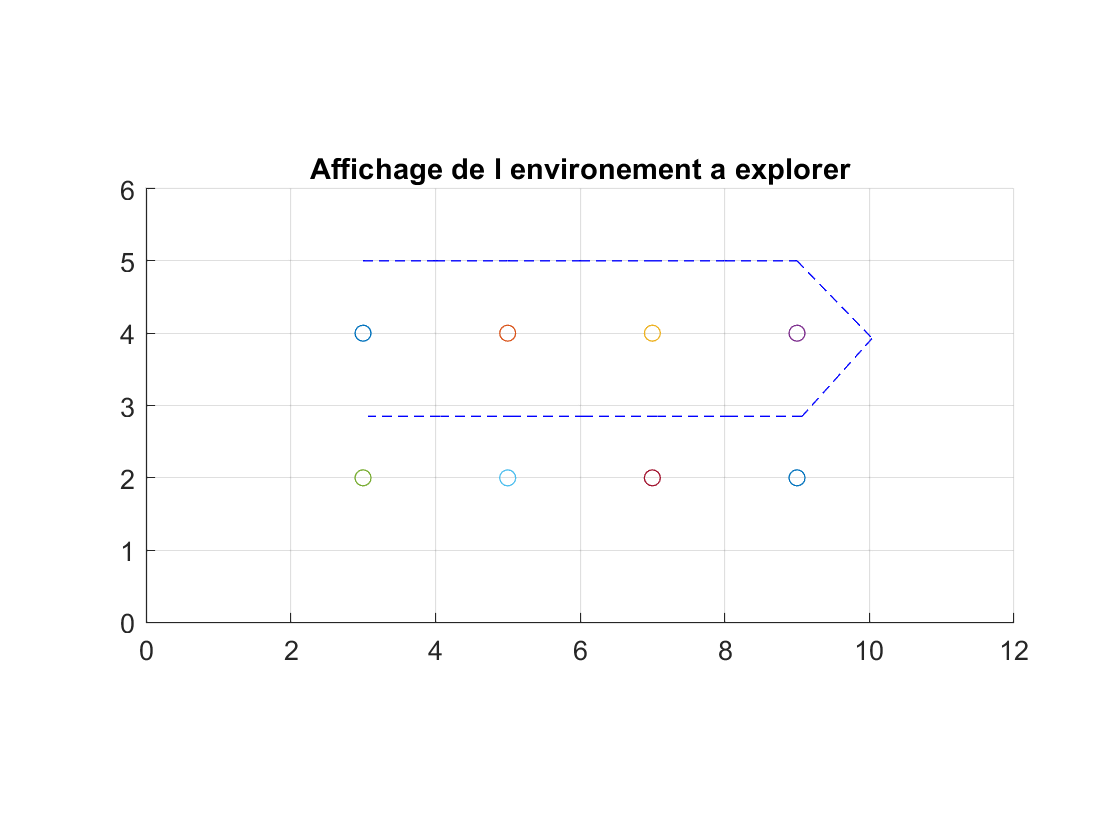

Xreel(:,k)=Fr2*Xreel(:,k-1);    

% Retour en ligne droite
for k=10:16
    Xreel(:,k)=Ft2*Xreel(:,k-1); 
end


for k = 1:length(Xreel)-1
    hold on
    plot(Xreel(1,max(k-1,1):k),Xreel(2,max(k-1,1):k),'--b');
    drawnow
    pause(deltaT)
end